sysdt = c2d(sys_rb, T_mpc, 'zoh'); % Discretise the rb model

Ad = sysdt.A;
Bd = sysdt.B;
Cd = sysdt.C;
[nx, nu] = size(Bd);

sysdt_comb = c2d(sys_comb, T_mpc, 'zoh');
Ad_comb = sysdt_comb.A;
Bd_comb = sysdt_comb.B;
nx_comb = size(Ad_comb, 1);

## Integral Action State Modifications

Add the integral state vector z


$$y = C x \\
z_{k+1} = z_k + (y_k - y_r) = z_k + C(x_k - x_r)

$$


ny = size(Cd, 1);
nz = ny;

nx_bar = nx + nz;

Ad_bar = [Ad, zeros(nx, nz); Cd*Ad, eye(nz)];
Bd_bar = [Bd; Cd*Bd];

## MPC Formulation

% umin = -Inf*ones(nu, 1);
% umax = Inf*ones(nu, 1);

umin = 0*ones(nu, 1) - F_e_real;
umax = 34*ones(nu, 1) - F_e_real;

xmin = -Inf*ones(nx_bar, 1);
xmax = Inf*ones(nx_bar, 1);

maxThrottleRate = 10 * T_mpc; % Maximum N/s in terms sample time steps
% maxThrottleRate = Inf; % Maximum N/s in terms sample time steps
dumin = [-maxThrottleRate; -maxThrottleRate];
dumax = [maxThrottleRate; maxThrottleRate];

% Objective function
% Q = diag(ones(1, nx));
Q_x = diag([1 1 1 5 5 5]);
Q_z = diag(0*ones(1, 3));
Q_bar = blkdiag(Q_x, Q_z); % Combine

R = 0.1*eye(nu);
% [QN,~,~] = idare(Ad, Bd, Q_x, R);
% QN_bar = idare(Ad_bar, Bd_bar, Q_bar, R);
QN_bar = Q_bar;

% Initial and ref states
% x0 = zeros(nx, 1);
x0 = [-.1; -.1; -.1; zeros(nx-3, 1)];
xr = [0; 0; 0; zeros(nx-3, 1)];
u0 = [0; 0];

% Integral action
y0 = Cd*x0;
z0 = y0 - Cd*x0;
x0_bar = [x0; z0];
xr_bar = [xr; zeros(nz, 1)];
yr = [0; 0; 0];

% Combined model
x0_comb = [x0; zeros(nx_comb-nx, 1)];

N = round(4 / T_mpc); % Time horizon
% N = 3;

% Linear objective
P = blkdiag(kron(speye(N), Q_bar), QN_bar, kron(speye(N), R));
P = (P + P')/2;
P = P + 1e-9 * speye(size(P));   % tiny regularizer
q = [repmat(-Q_bar*xr_bar, N, 1); -QN_bar*xr_bar; zeros(N*nu, 1)];

% Linear dynamics equality constraints
Ax = kron(speye(N+1), -speye(nx_bar)) + kron(sparse(diag(ones(N, 1), -1)), Ad_bar);
Bu = kron([sparse(1, N); speye(N)], Bd_bar);
Aeq = [Ax, Bu];
leq = [-x0_bar; zeros(N*nx_bar, 1)];
ueq = leq; % Equating leq and ueq to use inequality form as equality

% Absolute input and state constraints
Aineq = speye((N+1)*nx_bar + N*nu);
lineq = [repmat(xmin, N+1, 1); repmat(umin, N, 1)];
uineq = [repmat(xmax, N+1, 1); repmat(umax, N, 1)];

% Input rate constraints
Adu = kron(speye(N), -speye(nu)) + kron(sparse(diag(ones(N-1, 1), -1)), speye(nu));
Adu = [zeros(N*nu, (N+1)*nx_bar), Adu]; % Pad with left side with zeros because z contains states too

% ldu = [repmat(dumin, N, 1)];
% udu = [repmat(dumax, N, 1)];
ldu = [repmat(dumin - u0, N, 1)];
udu = [repmat(dumax - u0, N, 1)];
% ldu = [dumin - u0; repmat(dumin, N-1, 1)];
% udu = [dumax - u0; repmat(dumax, N-1, 1)];

idxdu = size(Aeq, 1) + size(Aineq, 1) + 1;

% OSQP constraints
A = [Aeq; Aineq; Adu];
l = [leq; lineq; ldu];
u = [ueq; uineq; udu];

prob = osqp;
% Setup workspace
% settings.verbose = 1;
settings.eps_abs = 1e-4;
settings.eps_rel = 1e-4;
settings.max_iter = 20000;
% settings.polish = 1;
settings.warm_start = 1;
prob.setup(P, q, A, l, u);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 2946, constraints m = 5892
          nnz(P) + nnz(A) = 20851
settings: linear system solver = qdldl,
          eps_abs = 1.0e-03, eps_rel = 1.0e-03,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



tsim = 15;
nsim = round(tsim / T_mpc); % Simulation steps

x_bar_log = zeros(nx_bar, nsim); % States
x_comb_log = zeros(nx_comb, nsim); % States
u_log = zeros(nu, nsim); % Inputs
x_pre = zeros(nx_bar, nsim, N); % State predictions over horizon at each step
tt_log = linspace(0, tsim, nsim);
tt_pre = zeros(nsim, N);

nlDynamics = false;

for i = 1 : nsim
    % Solve
    res = prob.solve();

    % Check solver status
    if ~strcmp(res.info.status, 'solved')
        disp('OSQP did not solve the problem!')
        break
    end

    % Apply first control input to the plant
    ctrl = res.x((N+1)*nx_bar+1:(N+1)*nx_bar+nu);

    % Simulate response, acts as new measurement
    x0_comb = Ad_comb*x0_comb + Bd_comb*(ctrl/k_fan);

    % Sense check: does controller work if direct fan input?
    % x0_comb(7:8) = ctrl; x0_comb(9:10) = [0; 0];

    % Calculate integral states
    y0 = Cd*x0_comb(1:nx);
    z0 = z0 + y0-yr;
    
    x0_bar = [x0_comb(1:nx); z0];

    % Log
    x_bar_log(:,i) = x0_bar;
    x_comb_log(:,i) = x0_comb;
    u_log(:,i) = ctrl;

    x_pre(:, i, :) = reshape(res.x(nx_bar+1:(N+1)*nx_bar), [nx_bar, N]);
    tt_pre(i, :) = linspace(tt_log(i), tt_log(i)+T_mpc*N, N);

    % Update initial state
    l(1:nx_bar) = -x0_bar;
    u(1:nx_bar) = -x0_bar;
    
    % Update rate constraint bounds for u0
    l(idxdu: idxdu+1) = dumin - ctrl;
    u(idxdu: idxdu+1) = dumax - ctrl;
    
    prob.update('l', l, 'u', u);
end

iter  objective    pri res    dua res    rho        time
   1   0.0000e+00   1.00e-01   1.00e+01   1.00e-01   5.17e-03s
  25   6.4581e-01   2.56e-03   4.42e-04   1.00e-01   8.26e-03s

status:               solved
number of iterations: 25
optimal objective:    0.6458
run time:             8.60e-03s
optimal rho estimate: 2.89e-02

iter  objective    pri res    dua res    rho        time
   1   6.6234e-01   1.00e-01   1.00e+01   1.00e-01   4.54e-04s
  25   1.0282e+00   2.15e-03   4.12e-04   1.00e-01   3.50e-03s

status:               solved
number of iterations: 25
optimal objective:    1.0282
run time:             3.85e-03s
optimal rho estimate: 2.31e-02

iter  objective    pri res    dua res    rho        time
   1   1.0420e+00   1.00e-01   1.00e+01   1.00e-01   4.10e-04s
  25   1.3668e+00   1.94e-03   3.83e-04   1.00e-01   3.46e-03s

status:               solved
number of iterations: 25
optimal objective:    1.3668
run time:             3.82e-03s
optimal rho estimate: 2.19e-02

iter  o

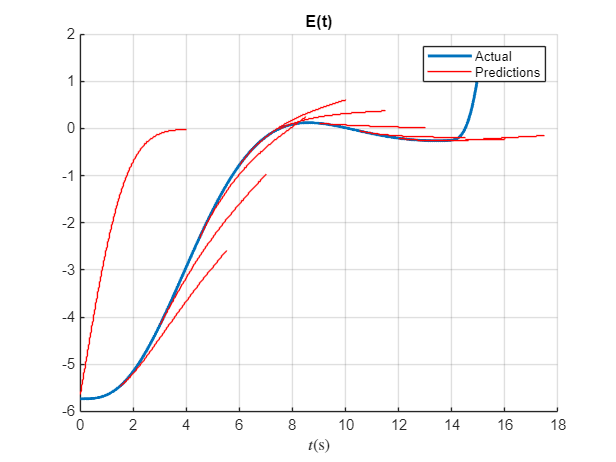

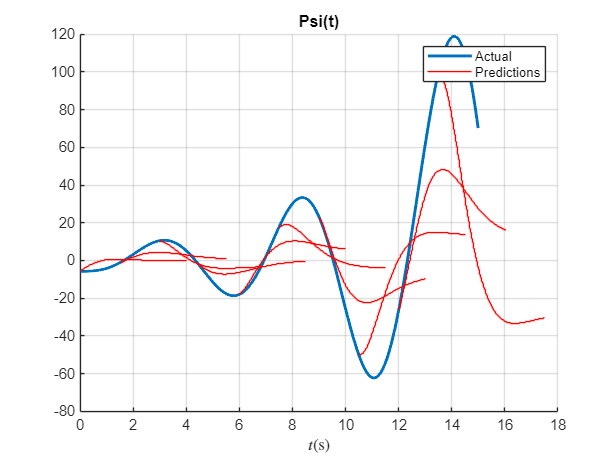

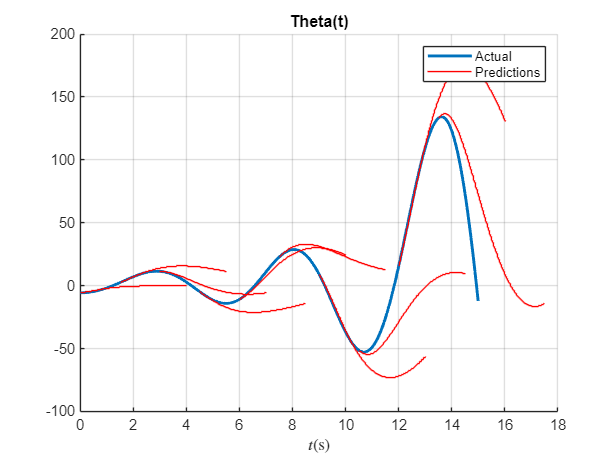

pre_samples = 1:100:length(tt_log); % Display predictions at intervals

for c = 1:3
    figure
    hold on
    plotTimeseries(tt_log, (180/3.14)*x_bar_log(c, :), 'Title', char(X_rb(c)))
    % plotTimeseries(tt_log, x_log(c, :), 'Title', 'Positions')
    stairs(tt_pre(pre_samples, :)', (180/3.14)*squeeze(x_pre(c, pre_samples, :))', 'r')
    hold off
    legend('Actual', 'Predictions')
end

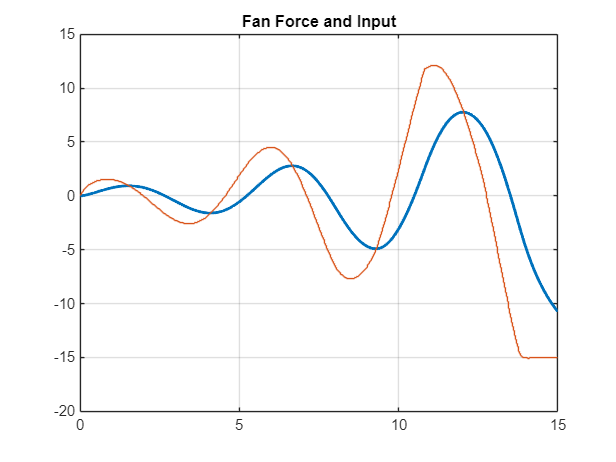

figure
plot(tt_log, x_comb_log(7, :), 'LineWidth', 2)
hold on
stairs(tt_log, u_log(1, :))
title('Fan Force and Input')
grid on
hold off

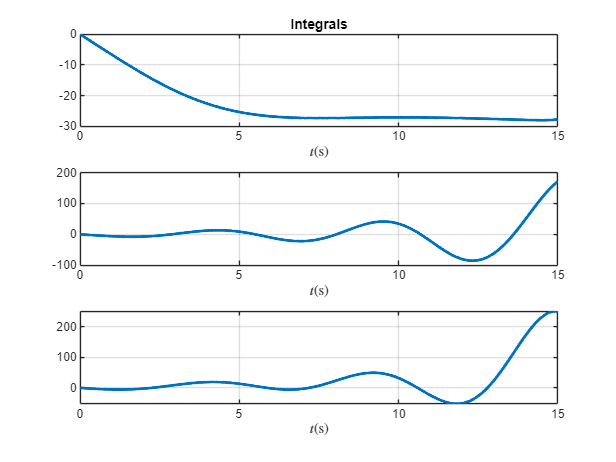


figure
plotTimeseries(tt_log, x_bar_log(7:9, :), 'Title', 'Integrals')

% plotTimeseries(tt_log, x_log(1:3, :), 'Title', 'Positions')
% plotTimeseries(tt_log, x_log(7:8, :) + F_e_real, 'Title', 'Fan Forces')
% plotTimeseries(tt_log, u_log, 'Title', 'Inputs', 'LineType', 'stairs')